%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Global Image Threshold, Multilevel Threshold             %
% Global Histogram Threshold and, Adaptive Image Threshold.%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Read a grayscale image into the workspace.
I = imread('IM_00240.TIF');

%Calculate a threshold using graythresh. The threshold is normalized to the range [0, 1].
level = graythresh(I)

level = 0.2118

level = 0.4941

level = 0.4941

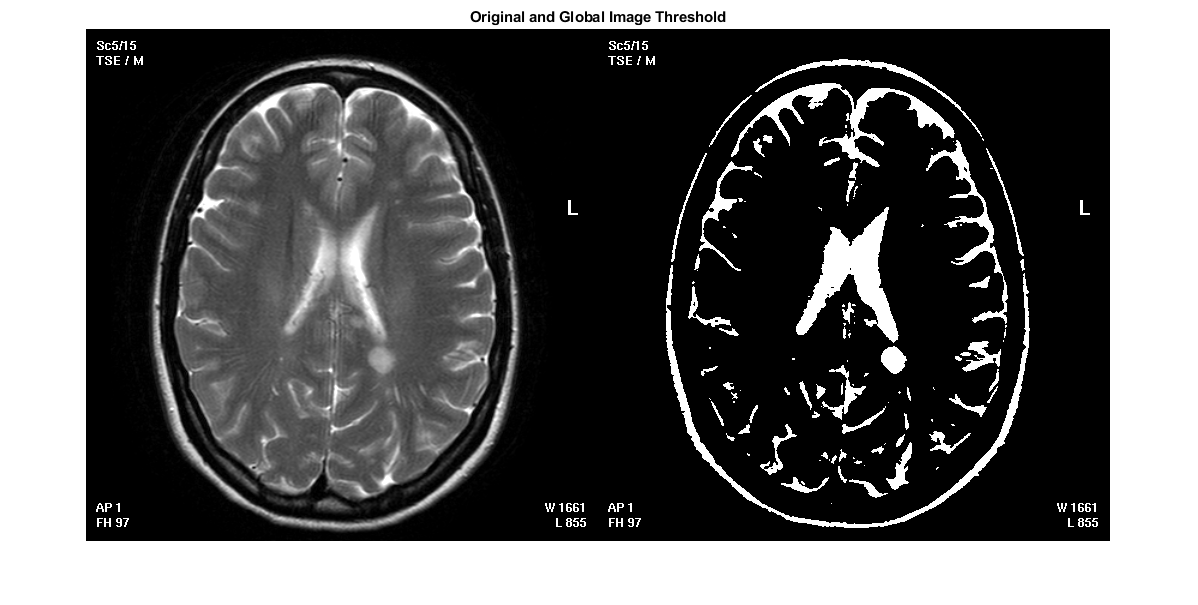


%Convert the image into a binary image using the threshold.
BW = imbinarize(I,level);

%Display the original image next to the binary image.
imshowpair(I,BW,'montage');title('Original and Global Image Threshold')

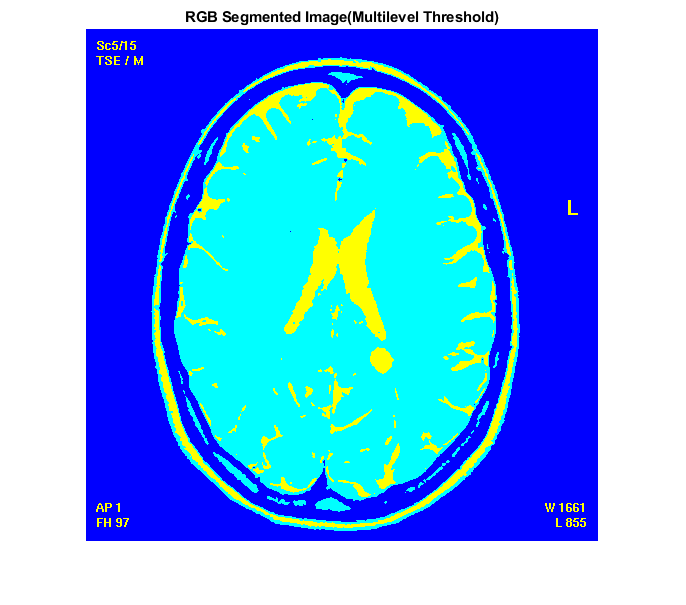


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculate two threshold levels.
thresh = multithresh(I,2);

%Segment the image into three levels using imquantize .
seg_I = imquantize(I,thresh);

%Convert segmented image into color image using label2rgb and display it.
RGB = label2rgb(seg_I); 	 
figure;
imshow(RGB)
axis off
title('RGB Segmented Image(Multilevel Threshold)')

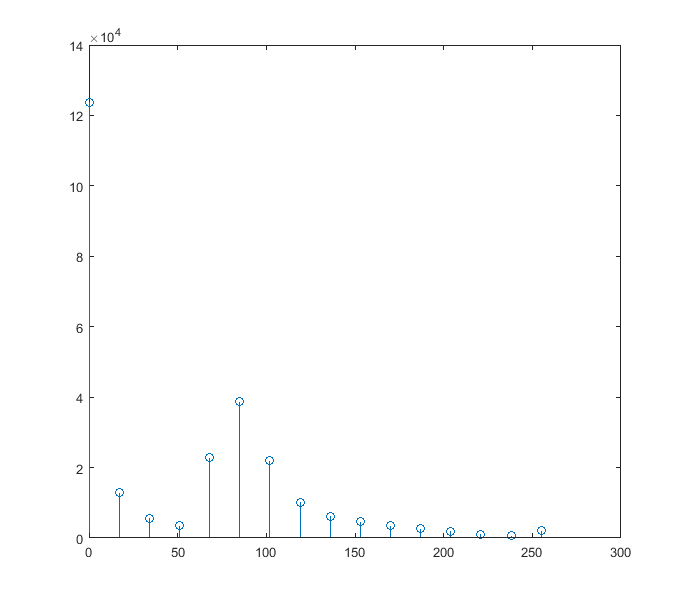


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculate a 16-bin histogram for the image.
[counts,x] = imhist(I,16);
stem(x,counts)

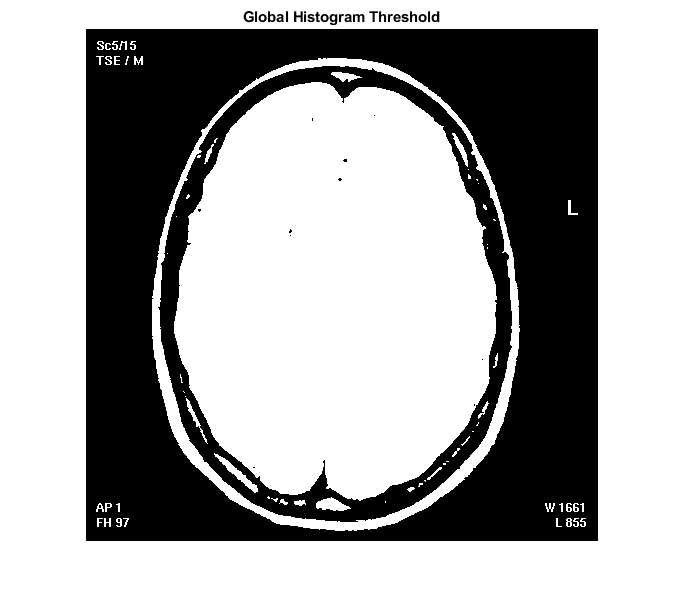


%Compute a global threshold using the histogram counts.
T = otsuthresh(counts);

%Create a binary image using the computed threshold and display the image.
BW = imbinarize(I,T);
figure
imshow(BW);title('Global Histogram Threshold')

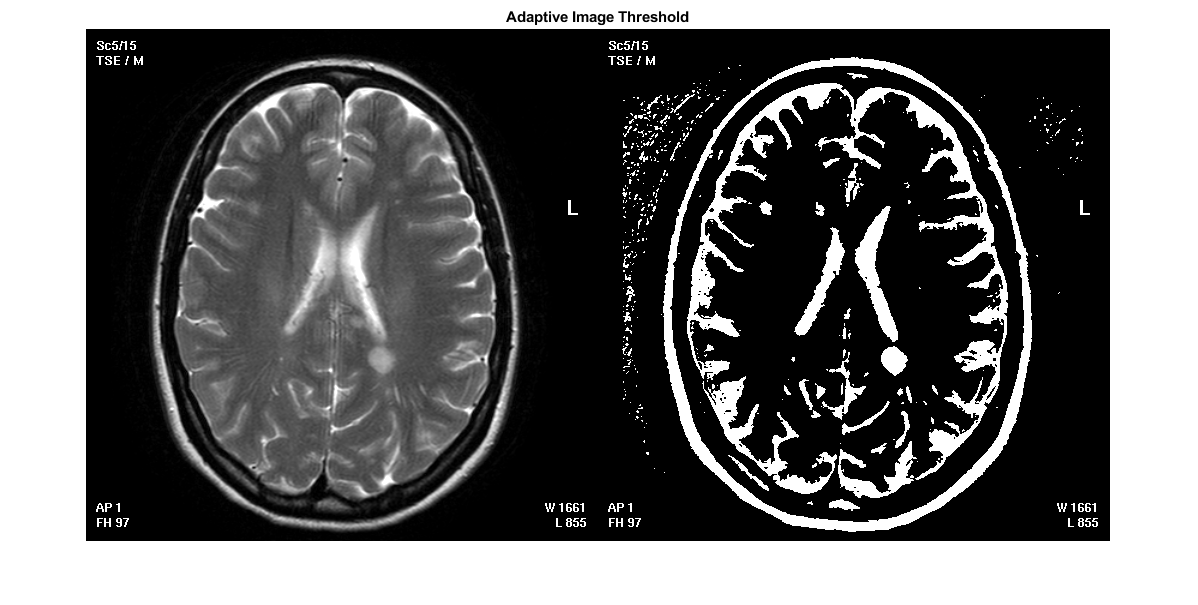


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Use adaptthresh to determine threshold to use in binarization operation.
T = adaptthresh(I, 0.4);

%Convert image to binary image, specifying the threshold value.
BW = imbinarize(I,T);

%Display the original image with the binary version, side-by-side.
figure
imshowpair(I, BW, 'montage');title('Adaptive Image Threshold')

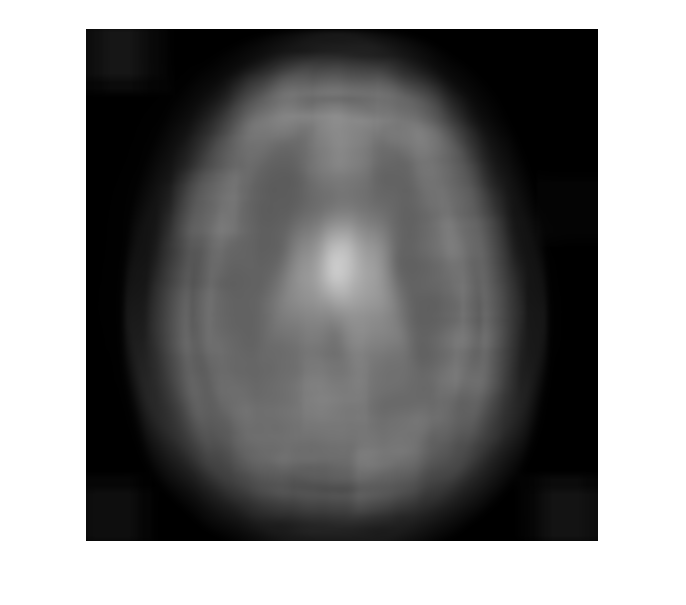


%Find Threshold and Segment Bright Text from Dark Background
T = adaptthresh(I,0.4,'ForegroundPolarity','bright');
figure
imshow(T)

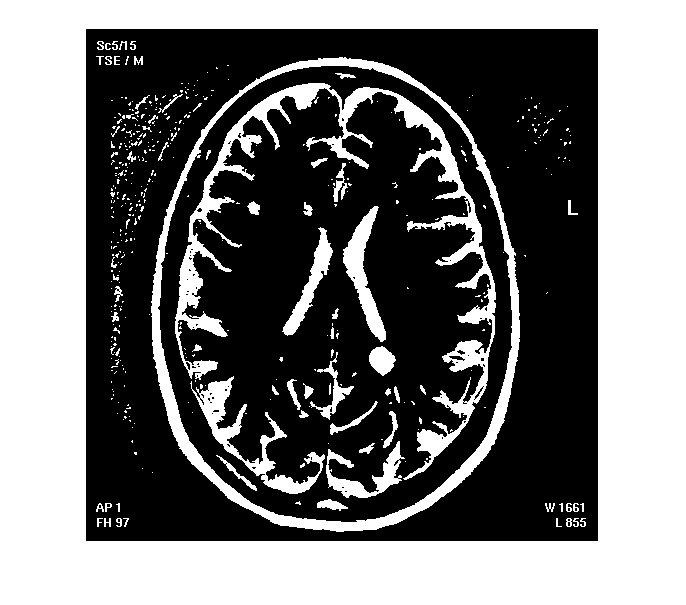


%Binarize image using locally adaptive threshold
BW = imbinarize(I,T);
figure
imshow(BW)